# Introducción al Matlab 

En esta primera sesión vamos a ver una introducción básica al programa y de forma más detalla la introducción y manipulación de vectores y matrices. En todas las sesiones vamos a trabajar con Live Script.

Ahora vamos a ir trabajando la práctica. Es importante recordar que:

- en las líneas de comando o instrucción (aquellas en las que aparece un número a la izquierda  y un recuadro sombreado), debes poner tú las instrucciones que luego se ejecutarán con el *Run* o *Run Section* o *Run and Advance*,  la salida será en la columna de la derecha por defecto.

- al seleccionar la opción texto se puede escribir el enunciado, apuntar cualquier explicación, introducir una fórmula. Como cualquier editor de textos.

- Después de realizar cada ejercicio es conveniente introducir un Section Break.

## **OPERACIONES ARITMÉTICAS**

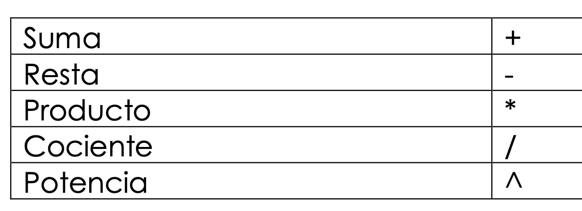

**Ejercicio 1.** Realiza las siguientes operaciones, $$\frac 8 4$3, $\frac{3+5}  4$, $\frac 4 {3+5}$, $4+\frac 1 {2^3}$ , $\frac {4+1} {2^3}$$

8/4*3, (3+5)/4, 4/(3+5), 4+1/2^3, (4+1)/2^3

ans =        6       


ans =        2       


ans =        1/2     


ans =       33/8     


ans =        5/8     


Puedes seguir practicando con los diferentes formatos de salida

format long

¿Cómo es la salida con este formato?

format short

¿Ves la diferencia?

format rat

Puedes completar la función del comando vpa(a,n)

vpa (pi, 10)

$$ans = 3.141592654$$

## **PROGRESIONES ARITMÉTICAS**

- Matlab construye los distintos elementos de una ***progresión aritmética ***(creciente) mediante la sentencia: 					

**primer elemento: salto positivo: último elemento **

**Ejercicio 2.** Describe:

a) los 10 primeros números pares 

2:2:20

ans =        2              4              6              8             10             12             14             16             18             20       


b) los 10 primeros números naturales

1:10

ans =        1              2              3              4              5              6              7              8              9             10       


c) los 10 primeros números impares a partir del 71

71:2:91

ans =       71             73             75             77             79             81             83             85             87             89             91       


d) los números impares entre -9 y 10 

-9:2:10

ans =       -9             -7             -5             -3             -1              1              3              5              7              9       


- **linspace,** permite definir el vector resultante de dividir cierto intervalo [a, b] en n-1 subintervalos iguales (partición equidistante) de la siguiente forma: 			

**                    linspace(a,b,n) ** 

**Ejercicio 3.** Consigue una partición del intervalo [1,19] en 13 subintervalos.

linspace(1,19,13)

ans =        1              5/2            4             11/2            7             17/2           10             23/2           13             29/2           16             35/2           19       


## **VECTORES**

Para escribir un vector se escriben sus componentes entre corchetes. Si se separan sus componentes con comas o espacios se obtiene un vector fila. Si se separan sus componentes por ; 

**Ejercicio 4. **Define los vectores `v=[3-5 4 8 0] y u=`$\left\lbrack \begin{array}{c}
3\\
-5\\
4\\
8\\
0
\end{array}\right\rbrack$

v=[3 -5 4 8 0], u=[3; -5; 4; 8; 0]

v =        3             -5              4              8              0       


u =        3       
      -5       
       4       
       8       
       0       


**Comandos relativos a vectores**

- **length(v)**, devuelve el número de componentes del vector

- **sum(v)**, calcula la suma de todas las componentes del vector

- **dot(u,v)**, calcula el producto escalar de dos vectores

- **cross(u,v)**, efectúa el producto vectorial de dos vectores

**Ejercicio 5. **Si u=(0 1 0) y v=(-1 1 1), cacula su producto escalar y el vectorial.

u=[0 1 0], v=[-1 1 1]

u =        0              1              0       


v =       -1              1              1       


dot(u,v)

ans =        1       


cross(u,v)

ans =        1              0              1       


## **Escritura de matrices**

Para escribir una matriz se escriben entre corchetes sus vectores fila separados por punto y coma. A su vez los componentes de cada vector pueden separarse por comas o con espacios en blanco.

**Ejercicio 6. **Escribe la matriz A=$\left\lbrack \begin{array}{cc}
0 & -3\\
2 & 1
\end{array}\right\rbrack$

A=[0 -3; 2 1]

A =        0             -3       
       2              1       


Visualización de componentes de una matriz.  Modificación de partes de una matriz.

 Se realiza mediante las siguientes instrucciones:

- `a(i,j)`  presenta el elemento de la matriz a de la fila i y la columna j

- `a(i,:)`  presenta la fila i-ésima

- `a(:,j)`  presenta la columna j-ésima

`a(fila_inicial:incr_fila:fila_final,col_inicial:incr_col:col_final) `

proporciona una submatriz formada por los elementos de intersección de las filas seleccionadas por los parámetros `fila_inicial, incr_fila y fila_final` con las columnas seleccionadas por los parámetros `col_inicial, incr_col` y `col_final.`

**Ejercicio 7. **Escribir una matriz 6x10 que contenga los números naturales del 1 al 60.  Extraer de ella la submatriz formada por los elementos de intersección de las filas y columnas pares.

M=[1:10; 11:20; 21:30; 31:40; 41:50; 51:60;]

M =        1              2              3              4              5              6              7              8              9             10       
      11             12             13             14             15             16             17             18             19             20       
      21             22             23             24             25             26             27             28             29             30       
      31             32             33             34             35             36             37             38             39             40       
      41             42             43             44             45             46             47             48             49             50       
      51             52             53             54             55             56             57             58             59             60       


N=[M(2,2):2:M(2,10);M(4,2):2:M(4,10);M(6,2):2:M(6,10);]

N =       12             14             16             18             20       
      32             34             36             38             40       
      52             54             56             58             60       


**Ejercicio 8. **Cambiar la segunda fila de la matriz a del ejemplo anterior por los números del 71 al 80 con incremento de 1.

M=[1:10; 71:80; 21:30; 31:40; 41:50; 51:60;]

M =        1              2              3              4              5              6              7              8              9             10       
      71             72             73             74             75             76             77             78             79             80       
      21             22             23             24             25             26             27             28             29             30       
      31             32             33             34             35             36             37             38             39             40       
      41             42             43             44             45             46             47             48             49             50       
      51             52             53             54             55             56             57             58             59             60       


**Generación de matrices en Matlab**

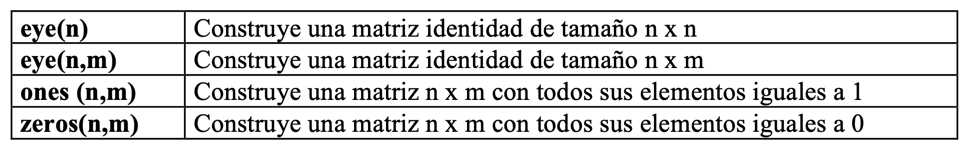

**Ejercicio 9. **Define las siguientes matrices:

a) La matriz identidad de orden 3

eye(3)

ans =        1              0              0       
       0              1              0       
       0              0              1       


b) una matriz de dimensión 4 con todos sus elementos iguales 4

4*ones(4,4)

ans =        4              4              4              4       
       4              4              4              4       
       4              4              4              4       
       4              4              4              4       


c) La matriz nula de dimensión 4

zeros(4,4)

ans =        0              0              0              0       
       0              0              0              0       
       0              0              0              0       
       0              0              0              0       


d) Una matriz 8x4 que reuna las matrices del apartado b y c

[4*ones(4,4);zeros(4,4)]

ans =        4              4              4              4       
       4              4              4              4       
       4              4              4              4       
       4              4              4              4       
       0              0              0              0       
       0              0              0              0       
       0              0              0              0       
       0              0              0              0       


d) Una matriz 4x8 que reuna las matrices del apartado b y c

[4*ones(4,4) zeros(4,4)]

ans =        4              4              4              4              0              0              0              0       
       4              4              4              4              0              0              0              0       
       4              4              4              4              0              0              0              0       
       4              4              4              4              0              0              0              0       


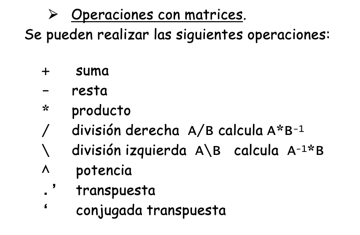

## FUNCIONES MÁS COMUNES

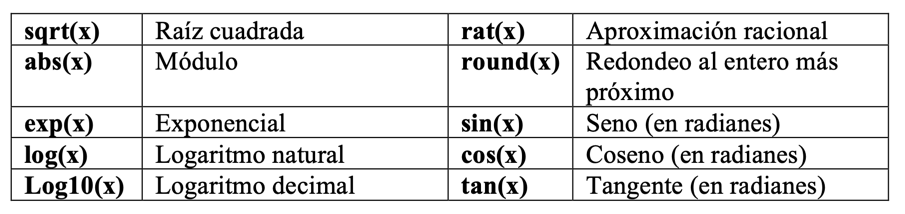

## Ejercicios propuestos

**Ejercicio 10**: Define un vector u de 30  elementos de forma que `u`(1)=-3 y `u`(30)=50.

u=[linspace(-3,50,30)]

u =       -3            -34/29          19/29          72/29         125/29         178/29         231/29         284/29         337/29         390/29         443/29         496/29         549/29         602/29         655/29         708/29         761/29         814/29         867/29         920/29         973/29        1026/29        1079/29        1132/29        1185/29        1238/29        1291/29        1344/29        1397/29          50       


**Ejercicio 11**: Define un vector  cuyos elementos sean los números pares menores o iguales que 60, sin contar el cero.

i=[60:-2:2]

i =       60             58             56             54             52             50             48             46             44             42             40             38             36             34             32             30             28             26             24             22             20             18             16             14             12             10              8              6              4              2       


**Ejercicio 12**: Calcula el producto escalar de los dos vectores de los ejercicios anteriores.

dot(u,i)

ans =    13640       


## NÚMEROS COMPLEJOS

Formas de representar los números complejos

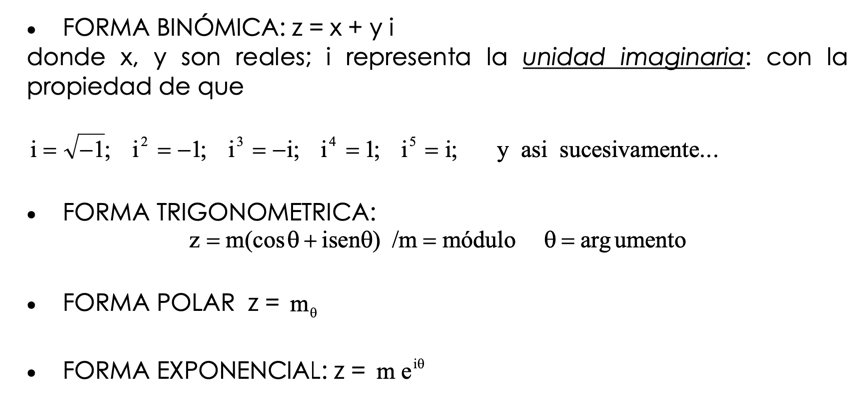

Podemos introducir un número complejo en forma binómica de varias formas, por ejemplo:

z_1=2+3i

z_1 =        2        +    3i      


z_2=complex(2,-3)

z_2 =        2        -    3i      


Para expresar el mismo número en cualquiera de las otras formas necesitamos conocer su módulo y su argumento, para ello usaremos

- *abs(z)*, para el módulo

- *angle(z)+2*pi, *para el argumento

Es conveniente definir los números de forma simbólica 

- z=sym(a+bi)  

**Ejercicio 13**. Escribe el siguiente número en forma binomial y calcula su módulo y su argumento

  

z=(complex(3,-2)+complex(0,-1)*complex(4,5))/(complex(1,1)+complex(2,1)+complex(3,1))

z =        2/3      -    4/3i    


abs(z)

ans =      963/646   


angle(z)+2*pi

ans =     2117/409   


**Ejercicio 14: **Calcula en Matlab:


$$\frac{\left(3-2i\right)-i\left(4+5i\right)}{\left(1+i\right)\left(2+i\right)\left(3+i\right)}$$



$$\textrm{Re}\left({\left(1-i\right)}^3 \right)$$



$$\textrm{Im}\left(\frac{1+2i}{3-4i}\right)$$


%Fíjate en la diferencia al definir como simbólica
syms z
z=complex(2)

z =        2        +    0i      


syms z
z=(complex(1,-1))^3

z =       -2        -    2i      


real(z)

ans =       -2       


syms z
z=complex(1,2)/complex(3,-4)

z =       -1/5      +    2/5i    


imag(z)

ans =        2/5     


**Ejercicio 15**: Expresa los siguientes números complejos en forma binómica y exponencial: 	 

ab1=complex(1,3)^4

ab1 =       28        -   96i      


ae1=abs(ab1)*exp(complex(0,angle(ab1)+2*pi))

ae1 =       28        -   96i      


**Ejercicio 16**: Calcua el módulo de los siguientes números complejos: 

al=complex(3,4)

al =        3        +    4i      


abs(al)

ans =        5       


bl=complex(1,1)/complex(1,-1)

bl =        0        +    1i      


abs(bl)

ans =        1       


cl=complex(0,1)^7+complex(0,1)^10

cl =       -1        -    1i      


abs(cl)

ans =     1393/985   


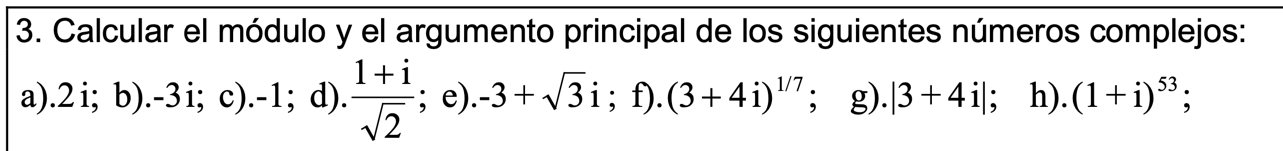

**Raíces de un número complejo:**

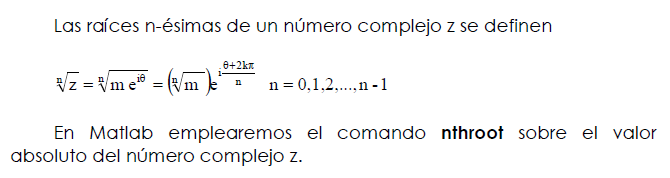

help nthroot

 nthroot Real n-th root of real numbers.
 
    nthroot(X, N) returns the real Nth root of the elements of X.
    Both X and N must be real, and if X is negative, N must be an odd integer.
 
    Class support for inputs X, N:
       float: double, single
 
    See also power.

    Documentation for nthroot
    Other uses of nthroot



**Ejemplo: **calculemos las raíces cúbicas de $1+i$:

**Resolución de ecuaciones:**

**Ejemplo: **Vamos a resolver la ecuación $z^2+z+1+i=0$:

Podemos hacerlo de dos formas. 

1. Con `roots:`

2. Con `Solve:`

% debemos definir previamente la variable simbólica

**Ejercicio 17: **Resuelve las siguientes ecuaciones:

a) $z^3+2=0$

syms z
solve(z^2+2)

$$ans = \left(\begin{array}{c} -\sqrt{2}\,\mathrm{i}\\ \sqrt{2}\,\mathrm{i} \end{array}\right)$$

b) $z^5+64=0$

syms z
solve(z^5+64)

$$ans = \begin{array}{l} \left(\begin{array}{c} -2\,2^{1/5}\\ 2\,2^{1/5}\,\left(\frac{\sqrt{5}}{4}+\frac{1}{4}-\sigma_{1}\right)\\ 2\,2^{1/5}\,\left(\frac{\sqrt{5}}{4}+\frac{1}{4}+\sigma_{1}\right)\\ 2\,2^{1/5}\,\left(\frac{1}{4}-\frac{\sqrt{5}}{4}+\sigma_{2}\right)\\ -2\,2^{1/5}\,\left(\frac{\sqrt{5}}{4}-\frac{1}{4}+\sigma_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{2}\,\sqrt{5-\sqrt{5}}\,\mathrm{i}}{4}\\ \sigma_{2}=\frac{\sqrt{2}\,\sqrt{\sqrt{5}+5}\,\mathrm{i}}{4} \end{array}$$

c) $(z^2+4)(z-1)^2=0$

syms z
solve((z^2+4)*(z-1)^2)

$$ans = \left(\begin{array}{c} 1\\ 1\\ -2\,\mathrm{i}\\ 2\,\mathrm{i} \end{array}\right)$$